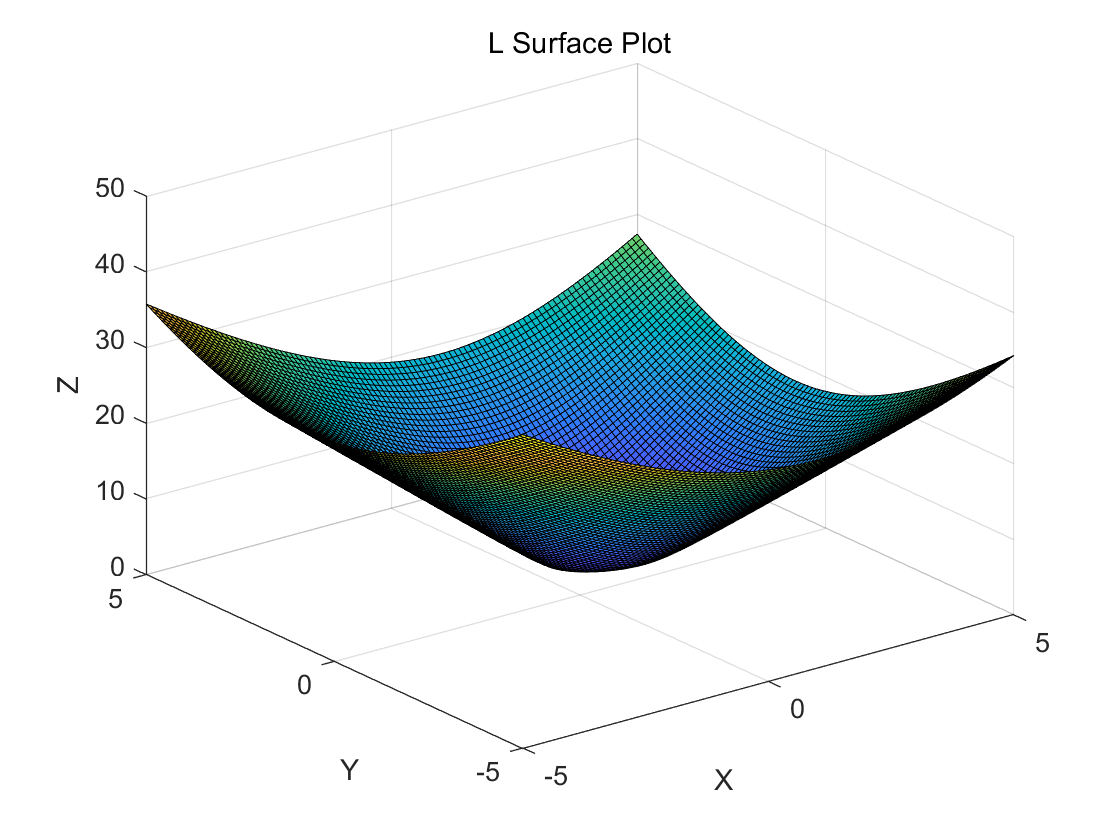

target_formation = [o1(1,1:2);o2(1,1:2);o3(1,1:2);o4(1,1:2)];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 定义函数
fun1 = @(x, y) norm(LaplaceMatrix(target_formation,false)-LaplaceMatrix([x,y;o2(1,1:2);o3(1,1:2);o4(1,1:2)],false),"fro");

% 定义绘图区间
x = linspace(-5, 5, 100);
y = linspace(-5, 5, 100);

% 创建坐标网格
[X, Y] = meshgrid(x, y);

% 计算梯度
len = size(X,1);
Z1 = zeros(len,len);
for i=1:len
    for j=1:len
        Z1(i,j) =  fun1(x(i), y(j));
    end
end

% 绘制梯度图
% [gradX, gradY] = gradient(z, x, y);
% figure;
% quiver(X, Y, -gradX, -gradY);
% xlabel('X');
% ylabel('Y');
% title('Gradient Plot');
% axis tight;
% axis equal;

% 绘制曲面图
figure;
surf(X, Y, Z1);
%contour(X,Y,Z1);
hold on
xlabel('X');
ylabel('Y');
zlabel('Z');
title('L Surface Plot');

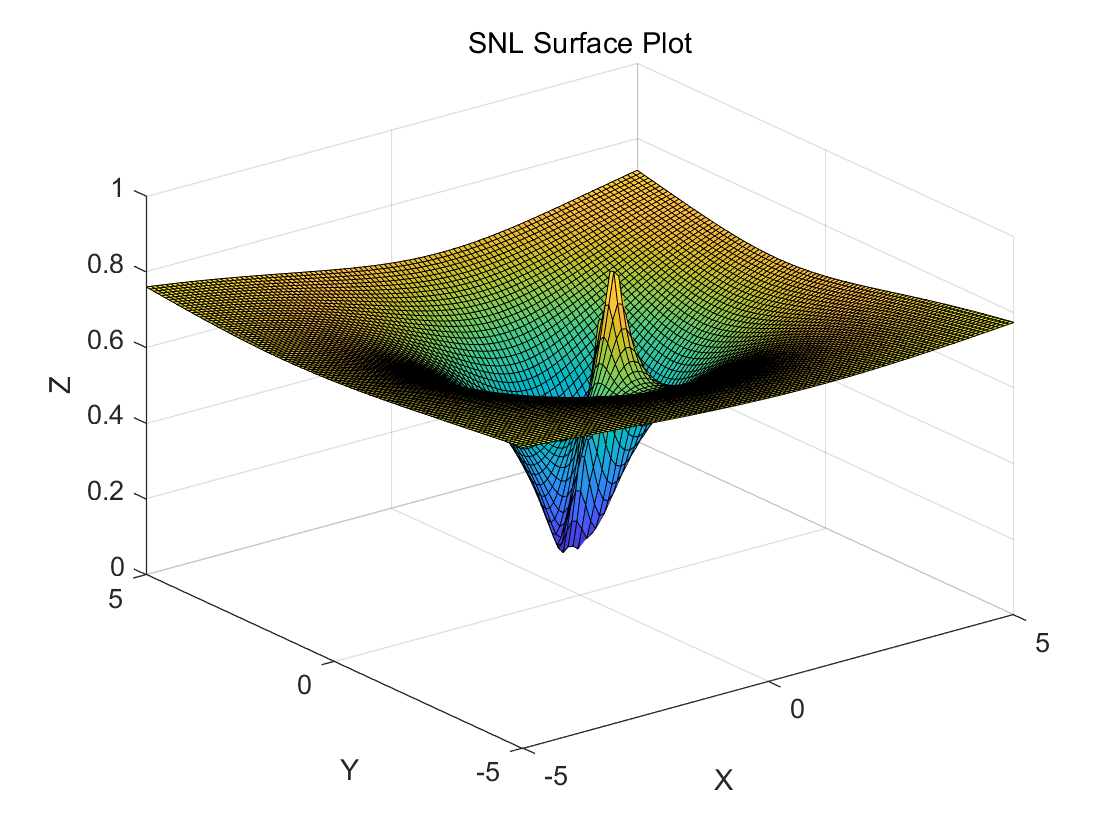


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 定义函数:极点为0.5,0.5
fun2 = @(x, y) norm(LaplaceMatrix(target_formation,true)-LaplaceMatrix([x,y;o2(1,1:2);o3(1,1:2);o4(1,1:2)],true),"fro");

% 定义绘图区间
x = linspace(-5, 5, 100);
y = linspace(-5, 5, 100);

% 创建坐标网格
[X, Y] = meshgrid(x, y);

% 计算梯度
len = size(X,1);
Z2 = zeros(len,len);
for i=1:len
    for j=1:len
        Z2(i,j) =  fun2(x(i), y(j));
    end
end



% 绘制梯度图
%[gradX, gradY] = gradient(z, x, y);
% figure;
% quiver(X, Y, -gradX, -gradY);
% xlabel('X');
% ylabel('Y');
% title('Gradient Plot');
% axis tight;
% axis equal;

% 绘制曲面图
figure;
surf(X, Y, Z2);
%contour(X,Y,Z2);
hold on
xlabel('X');
ylabel('Y');
zlabel('Z');
title('SNL Surface Plot');  

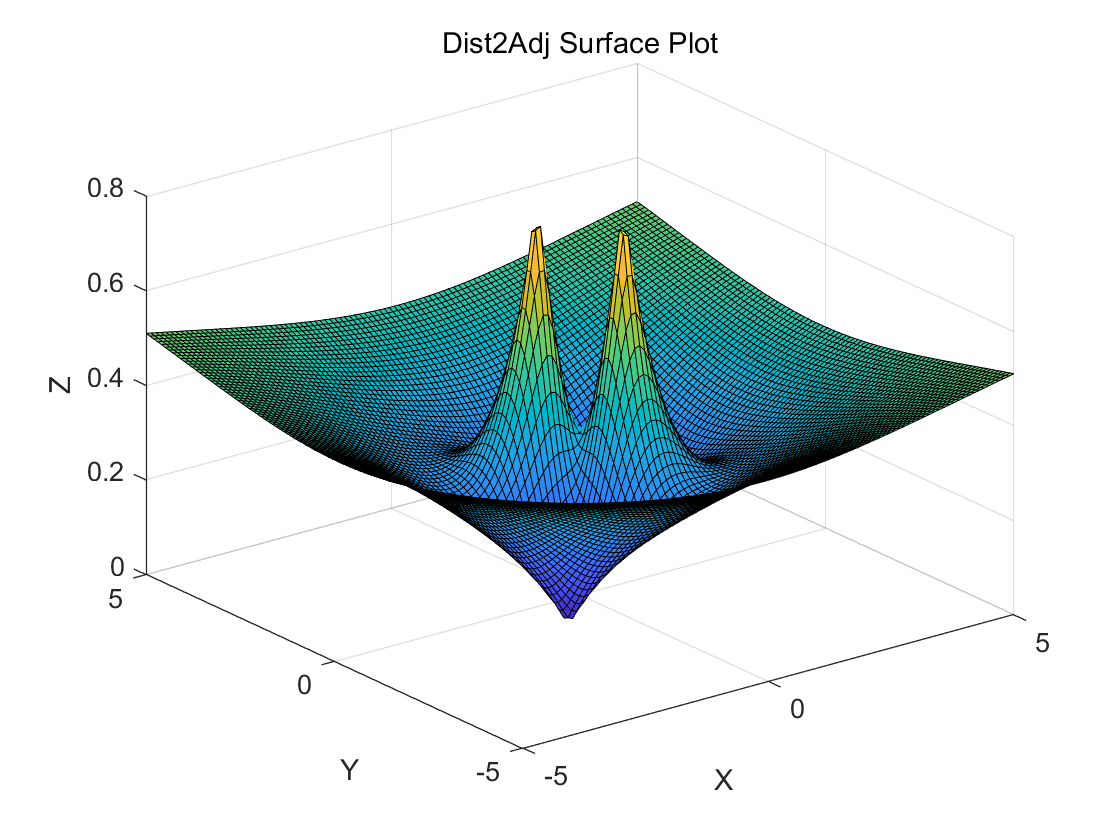


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 定义函数:极点应为
p2 = [-0.5,0.5];
p4 = [0.5,-0.5];
fun3 = @(x, y) norm(LaplaceMatrix([1,1;-0.5,0.5;0.5,-0.5],true)-LaplaceMatrix([x y;-0.5 0.5;0.5 -0.5;],true),"fro");

% 定义绘图区间
x = linspace(-5, 5, 100);
y = linspace(-5, 5, 100);

% 创建坐标网格
[X, Y] = meshgrid(x, y);

% 计算梯度
len = size(X,1);
Z3 = zeros(len,len);
for i=1:len
    for j=1:len
        Z3(i,j) =  fun3(x(i), y(j));
    end
end

% 绘制梯度图
% [gradX, gradY] = gradient(z, x, y);
% figure;
% quiver(X, Y, -gradX, -gradY);
% xlabel('X');
% ylabel('Y');
% title('Gradient Plot');
% axis tight;
% axis equal;

% 绘制曲面图
figure;
surf(X, Y, Z3);
%contour(X,Y,Z1);
hold on
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Dist2Adj Surface Plot');

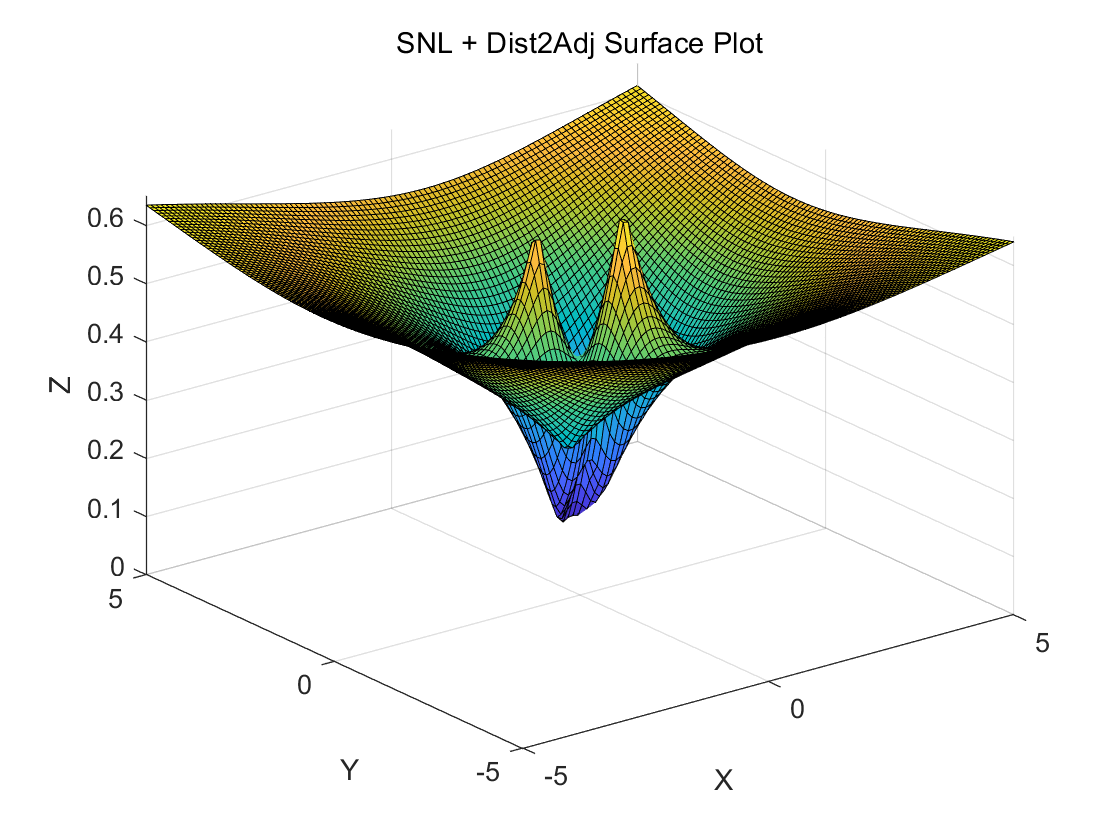


%%%%%%%%%%%%%%%%%%%%
% 绘制曲面图
figure;
surf(X, Y, (Z3+Z2)/2);
%contour(X,Y,Z1);
hold on
xlabel('X');
ylabel('Y');
zlabel('Z');
title('SNL + Dist2Adj Surface Plot');

Dist4Adjust=[];
for i=1:size(target_formation,1)
    j=i+1;
    if(j>size(target_formation,1))
        j=1;
    end
    pi = target_formation(i,:);
    pj = target_formation(j,:);
    Dist4Adjust(end+1) = norm(pi-pj);
end

%%%test for ||L-Ldes||fro between [0.5,0.5;-0.5,0.5;-0.5,-0.5;0.5,-0.5] and
%%%[1,1;-1,1;-1,-1;1,-1];
L1 = LaplaceMatrix( [0.8,0.8;-0.7,0.7;-0.7,-0.7;0.7,-0.7],false);
L2 = LaplaceMatrix([1,1;-1,1;-1,-1;1,-1],false);
s1 = norm(L1-L2,"fro");
s2 = L1*inv(L2);
s3 = norm(L1,"fro")-norm(L2,"fro");
s4 = norm(L1,"fro")/norm(L2,"fro");
s5 = s4/size(L1,1);

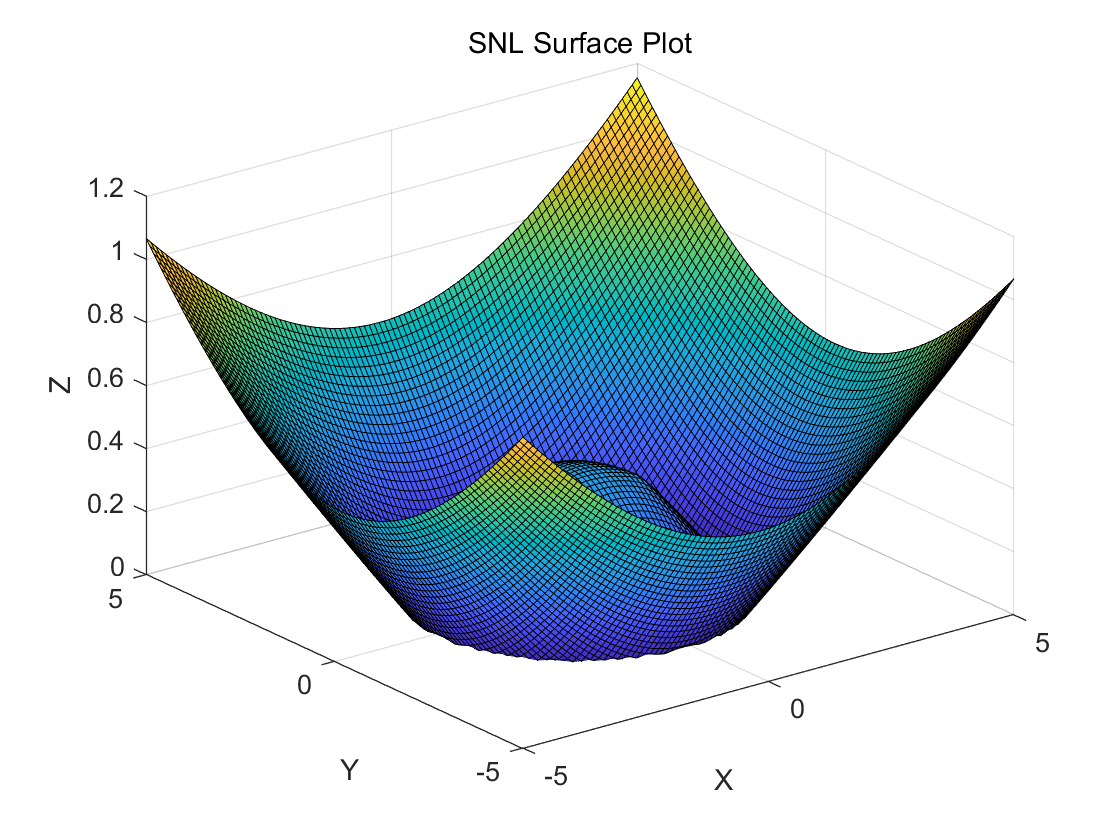

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 定义函数:极点为0.5,0.5
fun4 = @(x, y) norm(-1 + norm(LaplaceMatrix([x,y;-0.7,0.7;-0.7,-0.7;0.7,-0.7],false),"fro")/norm(LaplaceMatrix([1,1;-1,1;-1,-1;1,-1],false),"fro"));

% 定义绘图区间
x = linspace(-5, 5, 100);
y = linspace(-5, 5, 100);

% 创建坐标网格
[X, Y] = meshgrid(x, y);

% 计算梯度
len = size(X,1);
Z4 = zeros(len,len);
for i=1:len
    for j=1:len
        Z4(i,j) =  fun4(x(i), y(j));
    end
end
% 绘制梯度图
%[gradX, gradY] = gradient(z, x, y);
% figure;
% quiver(X, Y, -gradX, -gradY);
% xlabel('X');
% ylabel('Y');
% title('Gradient Plot');
% axis tight;
% axis equal;

% 绘制曲面图
figure;
surf(X, Y, Z4);
%contour(X,Y,Z2);
hold on
xlabel('X');
ylabel('Y');
zlabel('Z');
title('SNL Surface Plot');  

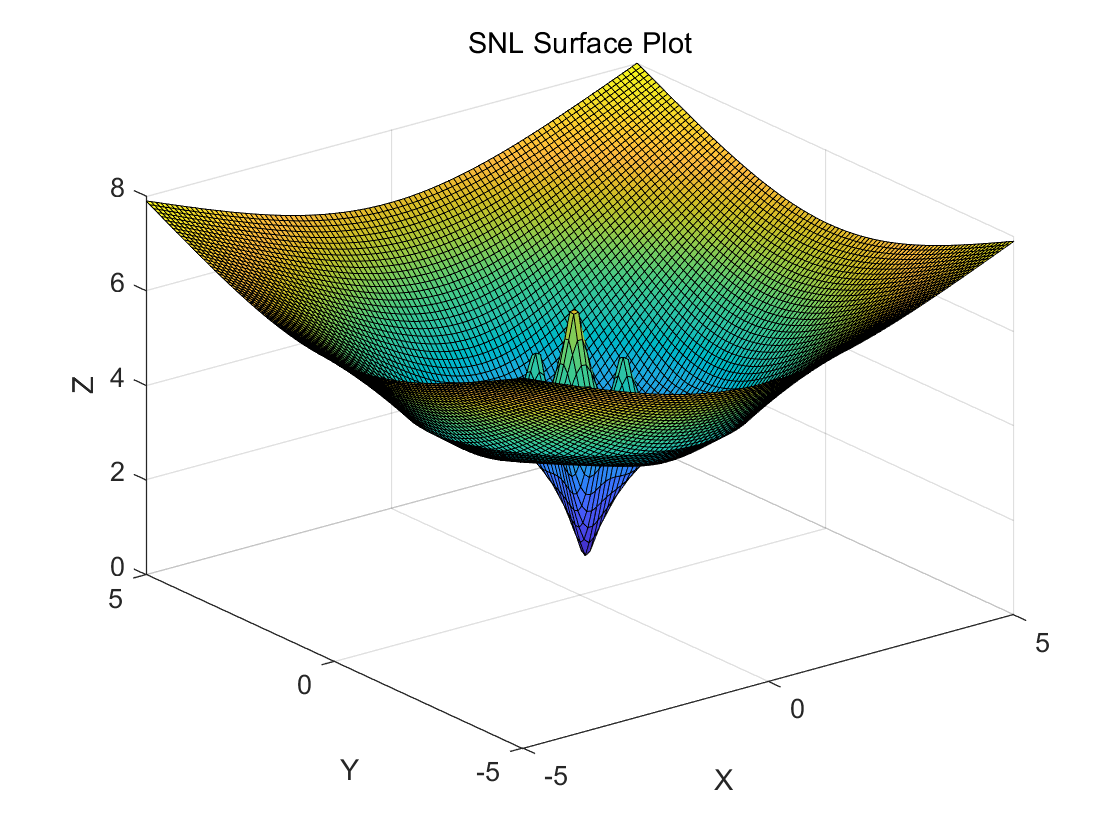


% 绘制曲面图
figure;
surf(X, Y, 10*Z2+Z4);
%contour(X,Y,Z2);
hold on
xlabel('X');
ylabel('Y');
zlabel('Z');
title('SNL Surface Plot'); 

fun_test = @(x) norm(-1 +  norm(LaplaceMatrix([x(1),x(2);-0.7,0.7;-0.7,-0.7;0.7,-0.7],false),"fro")/norm(LaplaceMatrix([1,1;-1,1;-1,-1;1,-1],false),"fro"));

x0 = [0,1];
min = fminsearch(fun_test,x0);
